%main program
%Was soll das Programm machen?
%Output: Zeitliche Entwicklung des Ordnungparameters 
%       -> o(t) 
%       -> Heatmap(t)
%Input: -> xyz Koordinaten
%       -> zugehoerige Quaternionen 
%       -> # Zeitschritte 
%       -> Anzahl Nachbarn
%       -> Anzahl Atome 
%
%
% determine t and nNeighbors and nAtoms 
% determine filenames of xyz and dump.quat(t)
% loop t
%       read coordinates out of xyz
%       read quaternions 
%       Determine order(...) of t
%       Visualize Heatmap(t)
%       give o(t) 
% end loop t
% give o(t)

clearvars; close all; clc;

## Initialize

tStart=20000000;           %starttime
tStep=1;        %timesstep
steps=1;            %number of steps
nNeighbors=4;
filename='dump.20000000.xyz';

read=@xyzread;
neighbors=@Neighbors;
ord=@order;
[natoms, c, x, y, z] = read(filename,steps);
listing=dir('dump.20000000.quat');
quat={listing.name};
o=zeros(natoms,1);
ordnung=zeros(steps);


## Calculate


for t=steps:steps
        dump=[c(:,t) x(:,t) y(:,t) z(:,t)];
        [Neigh, dist]=neighbors(nNeighbors,dump,natoms);
        disp('Zeitschritt:');
        disp(t);
        for i=1:natoms
%             if (mod(i,1000)==0)
%                 disp(i)
%             end
            o(i)=ord(i,Neigh(i,:), nNeighbors, quat{t}, dist);
        end

        ordnung(t)=mean(o);

end

Zeitschritt:


     1



## Plot

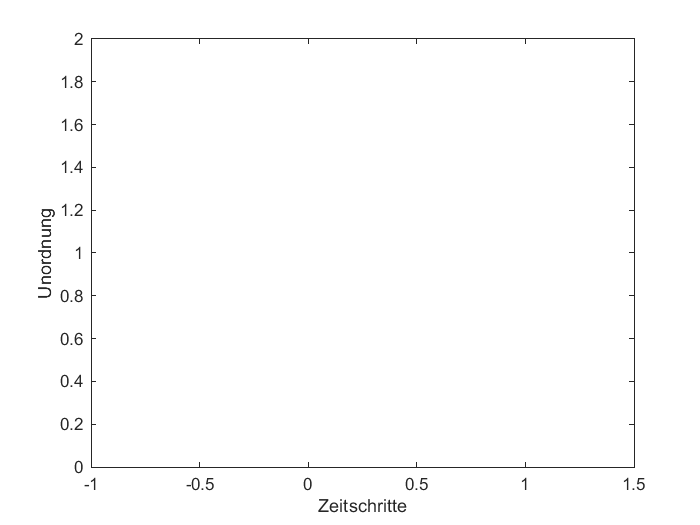

plot(ordnung,1:steps)
xlabel('Zeitschritte')
ylabel('Unordnung')